This example is based on the following publication:  

    S. A. Pertuz, A. Podlubne, and D. Goehringer, “An Efficient Accelerator for Nonlinear Model Predictive Control,” in *2023 IEEE 34th International Conference on Application-specific Systems, Architectures and Processors (ASAP)*, Jul. 2023, pp. 180–187. doi: [10.1109/ASAP57973.2023.00038](https://doi.org/10.1109/ASAP57973.2023.00038).  

## Nonlinear model predictive control (NMPC)

Nonlinear system described in a descrete-time state-space model by Eq. (1) and (2)


$$\begin{array}{l}
x\left(t+1\right)=f\left(x\left(t\right),u\left(t\right)\right),t\ge 0\;\;\;\;\;\;\;\;\;\;\;\left(1\right)\\
y\left(t\right)=h\left(x\left(t+1\right)\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)
\end{array}$$


where $f:R^n \times R^m \to R^n ,x\left(t\right)\in R^n$ is the state vector, $u\left(t\right)\in \textrm{Rm}$ is the system input vector, $y\left(t\right)\in R^{n\;}$ represents the controlled output vector, and $h:R^n \to R^n$is the function that maps the state vector to the controlled outputs.

Based on the system model, the cost function ($J$) to obtain the optimal control sequence:

$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{Error}\;\mathrm{state}\\
\min \;J\left(x\left(t\right),u\left(t\right)\;\right)\overset{\bigtriangleup }{=} \;\overbrace{\sum_{i=1}^{N-1} {\left\|\hat{x\;} \left(t+i\right)-r\left(t+i\right)\right\|}_Q^2 } +\;\;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\underbrace{{\left\|\hat{x\;} \left(N\right)-x_{\mathrm{ss}} \right\|}_{Q_f }^2 } \;\;\;\;\;\;+\;\;\;\;\;\;\;\;\;\underbrace{\sum_{i=0}^{N_C -1} {\left\|\hat{u\;} \left(t\right)-u_{\mathrm{ss}} \right\|}_R^2 } \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{Error}\;\mathrm{final}\;\mathrm{estate}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{Error}\;\mathrm{control}
\end{array}$ (3)

where $\hat{x\;} \left(t\right)$and $\hat{u\;} \left(t\right)$ are teh solver's estimated system state vector and control action inputs, respectively. $r\left(t\right)$is the system referene vector at state t, and $x_{\textrm{ss}}$and $u_{\textrm{ss}}$ are the vectors steady-state output and control values. $N$is the prediction horizon, $N_C$is contorl horizon$\left(N_C \le N\right)$ and $Q,Q_f \;\textrm{and}\;R$ are the diagonal weighting matrices for the intermediate state, steady-state, and control input deviation, respectively.

The system also subject to contraints on input $\left(u_{\min } ,u_{\max } \right)$, input variation $\left(\Delta \;u_{\min } ,\Delta \;u_{\max } \right)$and controlled outputs. $\left(y_{\min } ,y_{\max } \right)$.

NMPC scheme follows three steps which are repeated at the sampling time:

- Measure output $y\left(t\right)$ and the compute estimate state $x\left(t\right)$

- Compute ${u\left(t\right)}_{\textrm{opt}}$ the optimal control sequence, by solving the finite horizon optimal control problem;

- Apply the first optimal contorl action ${u\left(1\right)}_{\textrm{opt}}$ at instant k. 

## Particle Swarm Optimization

PSO is a nature-inspired algorithm of the swarm intelligence field that uses particles to search in an $N$-dimensional space $G$ to find the maximum or minimum value of a given function. Each particle has its position $u_i \in G\in R^n \;$and velocity $v_i \in R^n$ at a given iteration.

The canonical algorithm initializes each particle with uniformly distributed random values. At each iteration, the particle's position is evaluated by a cost function and stored in an individual best compared among the others and against the global best position $\left(y_{\textrm{best}} \right)$ if the evaluation is improved. Each best is compared among the others and against the global best position $\left(y_{\textrm{best}} \right)$. This $y_{\textrm{best}}$is updated at each iteration. Afterwards, each particle velocity and position are updated as in Eq. (4) and (5)

$v_{i,j}^{\left(k+1\right)} =v_{i,j}^{\left(k\right)} +\overset{\textrm{cognitive}\;\textrm{component}}{\overbrace{c_1 U_1 \left(y_{i,j}^{\left(k\right)} -u_{i,j}^{\left(k\right)} \right)} } +\overset{\textrm{social}\;\textrm{component}}{\overbrace{c_2 U_2 \left(y_{\textrm{sj}}^{\left(k\right)} -u_{i,j}^{\left(k\right)} \right)} }$ (4)

$u_{i,j}^{\left(k+1\right)} =u_{i,j}^{\left(k\right)} +v_{i,j}^{\left(k+1\right)}$                                               (5)

where $k\in \left(1,k_{\max } \right)$ represents the current iteration $i\in \left(1,S\right)$is the particle index, and $j\in \left(1,\textrm{Dim}\right)$ is the index for the particle's dimension. $w$ is the inertia factor, which starts with a high value helping the particles explore the search space faster and then decays linearly with each iteration. $U_1 \;\textrm{and}\;U_2$ are random numbers in the interval $\left\lbrack 0,1\right\rbrack$. $v\;\textrm{and}\;u$are limited by $\left\lbrack -v_{\max } ,v_{\max } \right\rbrack$ and $\left\lbrack u_{\min } ,u_{\max } \right\rbrack$. $c_1$is the cognitive coefficient (confidence in the particle's best), and $c_2$is the social coefficient (coefficient in the global best).

## PSO Enhancements for NMPC

A variation fo the PSO, described in [1], use available knowledge about a specific problem. In this work, the variation is adapted to NMPC where the particles are initialized with the solution from the previous NMPC run. In this case, this solution containing $N_C$control actions is shifted by one sampling period, discarding the first control. The variaiton is further enhanced by initializing one of the particles with all dimensions equal to $u_{\textrm{ss}}$ (control value at steady state $x_{\textrm{ss}}$). Similarly, another particle is initialized with with a velocity equal to zero and the local best $y=x_{\textrm{ss}}$. This procedure improves the control signal noise and maintains system stability at a steady state.

Considering all the previous modifications, the overall NMPC strategy is described in Algorithm 1.

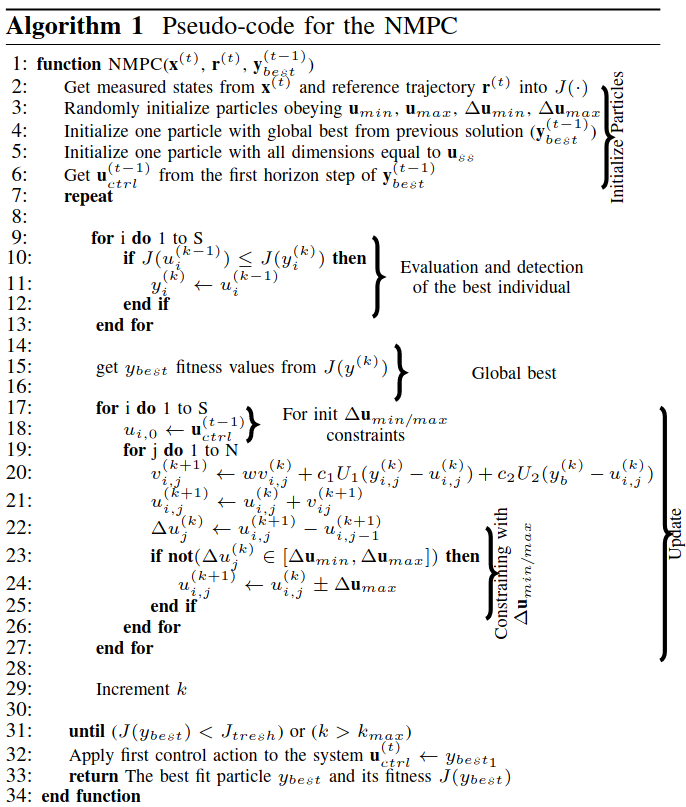

function [y_best, J_best] = NMPC(x_t, r_t, y_best_prev, J_thresh, k_max, u_min, u_max, delta_u_min, delta_u_max, w, c1, c2, Q, Qf, R, N, Nc, u_ss, x_ss)
    % Initialize parameters
    S = 10;  % Number of particles
    Dim = Nc; % Control horizon
    particles = zeros(S, Dim);
    velocities = zeros(S, Dim);

S = 10

Dim = 1

    % Initialize particles

w = 0.9000

    particles(1, :) = y_best_prev;
    particles(2, :) = u_ss;
    for i = 3:S

Q_pendulum =      2     0
     0     1


        particles(i, :) = u_min + (u_max - u_min) * rand(1, Dim);

Qf_pendulum =     0.0150         0
         0    0.0100


    end

R_pendulum = 0

    
    % Initialize velocities

k_max = 100

    velocities(1, :) = 0;

c1 = 2.1000

    for i = 2:S

c2 = 1

        velocities(i, :) = -delta_u_max + 2 * delta_u_max * rand(1, Dim);
    end
    
    % Initialize best positions
    p_best = particles;
    p_best_cost = inf(S, 1);

u_min_pendulum = -50

u_max_pendulum = 50

    % Evaluate initial particles

delta_u_min_pendulum = -2

    for i = 1:S

delta_u_max_pendulum = 2

        p_best_cost(i) = computeCost(particles(i, :), x_t, r_t, x_ss, u_ss, Q, Qf, R, N, Nc);
    end
    

Ts = 0.1000

    % Global best
    [J_best, best_idx] = min(p_best_cost);
    y_best = p_best(best_idx, :);
    
    k = 0;
    while J_best > J_thresh && k < k_max
        for i = 1:S
            % Update velocities
            for j = 1:Dim
                r1 = rand();
                r2 = rand();
                velocities(i, j) = w * velocities(i, j) ...
                    + c1 * r1 * (p_best(i, j) - particles(i, j)) ...
                    + c2 * r2 * (y_best(j) - particles(i, j));
                
                % Constrain velocities
                velocities(i, j) = max(min(velocities(i, j), delta_u_max), -delta_u_max);
            end
            
            % Update positions

y_best_t_minus_1_pendulum = 0

            particles(i, :) = particles(i, :) + velocities(i, :);
            

J_thresh = 2

            % Constrain positions
            particles(i, :) = max(min(particles(i, :), u_max), u_min);

Nc = 1

N = 10

            % Evaluate new position
            cost = computeCost(particles(i, :), x_t, r_t, x_ss, u_ss, Q, Qf, R, N, Nc);

Unable to perform assignment because the size of the left side is 2-by-1 and the size of the right side is 2-by-2.

Error in efficient_NMPC_accelerator>predictState (line 103)
    x_hat(:, 1) = x_t;

Error in efficient_NMPC_accelerator>computeCost (line 77)
    x_h

            
            % Update personal best
            if cost < p_best_cost(i)
                p_best(i, :) = particles(i, :);
                p_best_cost(i) = cost;
            end
        end
        
        % Update global best
        [current_best_cost, best_idx] = min(p_best_cost);
        if current_best_cost < J_best
            J_best = current_best_cost;
            y_best = p_best(best_idx, :);
        end
        
        k = k + 1;
    end
end

### Cost function

The cost function (Eq. 3) includes a predictor that adopts a $4\textrm{th}$-order Runge-Kutta (RK4) method [2], using four weighted predictions of the system using the model at each time step, obtaining a more accurate prediction. This method is included as one of the main parts of the cost function, which are: (1) the error adder, (2) the RK4 algorithm, and (3) the system model. Furthermore, the cost function can be generalized with different controlled systems, leaving the last two modules and only changing the first. In this way, the system model, which implements the differential equations, can be exchanged depending on the application and the constraints. For the *Error State *and *Error* *Final State*, it is necessary to predict the system's states with the horizon inputs given by each particle $\left(\hat{y\;} \right)$.

function cost = computeCost(u_hat, x_t, r_t, x_ss, u_ss, Q, Qf, R, N, Nc)
    % Placeholder for state prediction using RK4 or other methods
    x_hat = predictState(x_t, u_hat, N);
    
    % Compute cost
    cost = 0;
    
    % Error State
    for i = 1:N-1
        error_state = x_hat(:, i) - r_t(:, i);
        cost = cost + error_state' * Q * error_state;
    end
    
    % Error Final State
    error_final_state = x_hat(:, N) - x_ss;
    cost = cost + error_final_state' * Qf * error_final_state;
    
    % Error Control
    for i = 1:Nc-1
        error_control = u_hat(:, i) - u_ss;
        cost = cost + error_control' * R * error_control;
    end
end

function x_hat = predictState(x_t, u_hat, N)
    % Placeholder for state prediction using RK4 or other methods
    % Implement the state prediction logic here
    x_hat = zeros(size(x_t, 1), N);
    x_hat(:, 1) = x_t;
    % Example prediction loop
    h = 1.0
    F_xy = @(t,r) 3.*exp(-t)-0.4*r;
    for i = 2:N
        % Update x_hat(:, i) based on the model
        k_1 = F_xy(x(i),x_hat(i));
        k_2 = F_xy(x(i)+0.5*h,x_hat(i)+0.5*h*k_1);
        k_3 = F_xy((x(i)+0.5*h),(x_hat(i)+0.5*h*k_2));
        k_4 = F_xy((x(i)+h),(x_hat(i)+k_3*h));
        x_hat(i+1) = x_hat(i) + (1/6)*(k_1+2*k_2+2*k_3+k_4)*h;  % main equation
    end
end

% calculates ODE using Runge-Kutta 4th order method
% by Author Ido Schwartz
% clc;                                               % Clears the screen
% clear all;
% h=1.5;                                             % step size
% x = 0:h:3;                                         % Calculates upto y(3)
% y = zeros(1,length(x)); 
% y(1) = 5;                                          % initial condition
% F_xy = @(t,r) 3.*exp(-t)-0.4*r;                    % change the function as you desire
% for i=1:(length(x)-1)                              % calculation loop
%     k_1 = F_xy(x(i),y(i));
%     k_2 = F_xy(x(i)+0.5*h,y(i)+0.5*h*k_1);
%     k_3 = F_xy((x(i)+0.5*h),(y(i)+0.5*h*k_2));
%     k_4 = F_xy((x(i)+h),(y(i)+k_3*h));
%     y(i+1) = y(i) + (1/6)*(k_1+2*k_2+2*k_3+k_4)*h;  % main equation
% end

### Optimized Parallelized Hardware Architecture

PSO has exploitable characteristics for FPGA implementation, which is also true for the proposed FPGA implementation and also for the proposed NMPC. Algorithm 1 describes the NMPC and , in it, the main loop (on line 7) represents each iteration. The inner loops that compose the *update* and *evaluation and detection of best individual (*on line 9 and 17) can be executed in parallel as these loops are not dependant on previous iterations.

On the other hand the loop on line 19 is where the particles's postion and velocity are updated, is iteration-dependant. This dependency is because each dimension represents a control action that obeys the $\Delta u$ constraints( See constraint rules with $\Delta u_{\min /\max }$ bracket). However, despite this dependency, each particle can be updated in parallel. Finally, the global best bracket, which compares the local best of each particle, is naturally a parallel procedure, provided all values can be organized in a comparison tree.

In the *evaluation and detection of best individual *block, the cost function $\left(J\left(\cdot \right)\right)$ does the following steps:

- fetch the particle's control horizon $u_i^{k+1}$, of the current $i$-pariticle and $\left(k+1\right)$- time step, from update particles block and broadcast it with $u$*guess* block,

- computes the system states over the prediction horizon $\left(N\right)$,

- calculates the error state,

- error final state and,

- error control in Eq. 3

- sums each error separately, and

- makes the final sum.

All previous components can be executed in a coordinated dataflow manner, as shown in Fig. 1a

Another essential thing to mention about the *cost function *is that it does not need to wait for the *update* loop to finish to start computing. Instead, every time a new $u_{i,j}^{k+1}$is generated, it can execute one step horizon and perform all the steps mentioned for one dimension, thus merging and pipelining both the *update* and* evaluation and detection of the best individual *loops (see Fig. 1b). This novel datflow-pipelined approach for the NMPC not only makes processing faster but also saves memory since only the current predicted state $\left({\hat{x\;} }^k \right)$has to remain in memory.

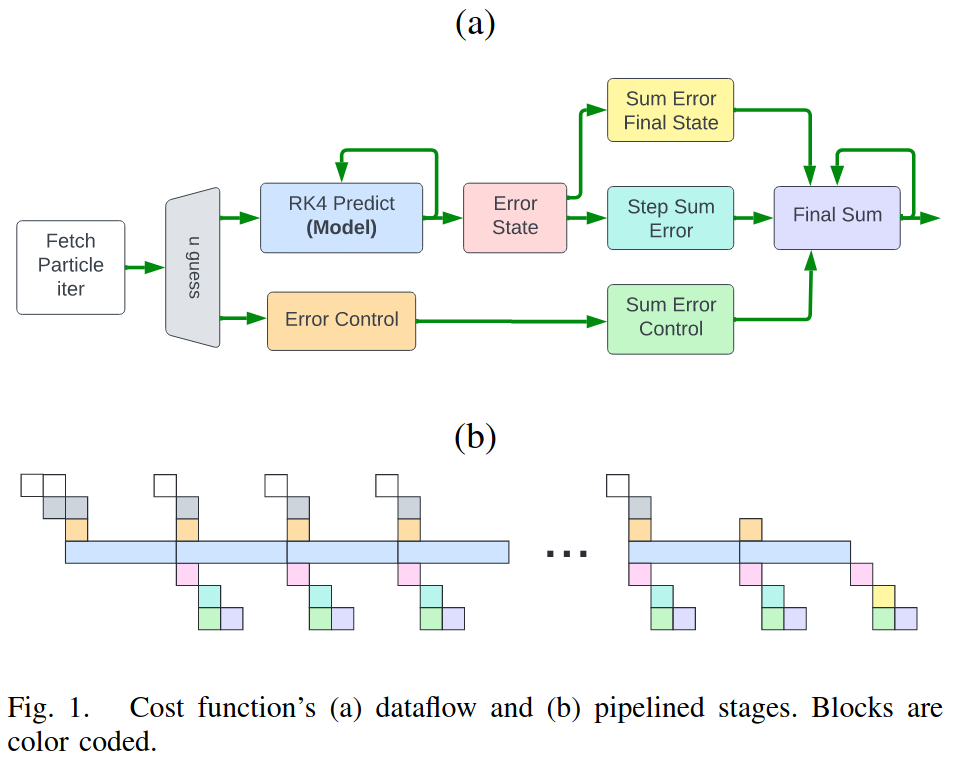

### Block design hardware architecture

The NMPC should be flexible enough to be applied to different system models with a configurable number of inputs, outputs, prediction, and control horizons, among all the other parameters listed in Table I. To that end, an architectural decision was made to use half-precision floating-point arithmetic for the model computation providing better precision and a broader dynamic range for models whose limits might not be easy to determine at design time. A fixed-point representation is used for all other hardware components since they involve only the particles' values and error calculation. A preliminary analysis showed that 32-bit (16-bit integer) provides a good compromise between hardware utilization and precision.

The hardware schematic of the NMPC accelerator are depicted in Fig.2 where the blocks in blue are developed in HLS. *fit eval & local min *module (short for *evaluation and detection of the best individual*) represents the highest computational cost. It is composed of parallelized ${\textrm{CostF}}_i$ sub-modules that integrate the RK4 predictor (see Section IV-A) and a system model module (see Fig 1a). The system model module implements the differential equations. These ${\textrm{CostF}}_i$ moudules are implemented in parallel, calculate the particles state error, detect the local minimum and then update the same memory. This module also limits the usage of multipliers and adders to reduce FPGA resource utilization by leverating the HLS pragma allocation.

The other main sub-modules of the NMPC algorithm represent each PSO step, namely, *initialize particles*, *update particles*, and *detect global best*. As previously mentioned, these blocks are parallelized and pipelined for faster processing. Other necessary auxiliary blocks are the *pseudo random generator *which is designed in a pipelined way that allows it to generate a pseudo-random number every clock cycle on the interval $\left\lbrack 0,1\right\rbrack$ when enabled. The generator is based on the linear congruential generator algorithm [3].

To reduce the register usage, the PSO particle variables $\left(u,y,v,\textrm{systemconstraints}\;\textrm{and}\;\textrm{PSO}\;\textrm{parameters}\right)$are stored in internal FPGA RAM blocks (BRAM or LUT depending on their size). The BRAM are 1WNR (1 write N reads, where $N=S$) memory blocks, and each memory address for all blocks stores 32-bit fixed-point variables for $u,y,v$ represents one dimension of each particle. One write and N read is sufficient to increase the memory throughput for each loop because esach dimension of all particles can be accessed simultaneously for parallel processing.

All these sub-module are coordinated by an *KPSO FSM* responsible for implementing the pipeline strategy between update and cost function depicted in Fig. 1.

### Accelerator Interfacing and Customization

The NMPC architecture can be used in conjuction with a processor with an interface wrapper based on middleware specifications, such as ROS1/2, to ease their integration. For this interfacing, tool in [4], is used to automate the accelerator interface capable of quickly establishing incoming and outgoing communication from/to existing robotics systems.

The NMPC accelerator can be configured for any system, as long as the user provides the customization parameters on Table I and the system state space equations in C++ code respecting the function prototype:

% template <typename _model_real> void __model(
%    _model_real *state_dot, 
%    _model_real *state, 
%    _model_real *control)

The accelerator is template-based and allows the user to change the model and some structural customization parameters. These structural parameters determine the memory size and the number of instances, such as the prediction and control horizons, the number of particles, the number of states, and control actions of each system are all configured by these parameters.

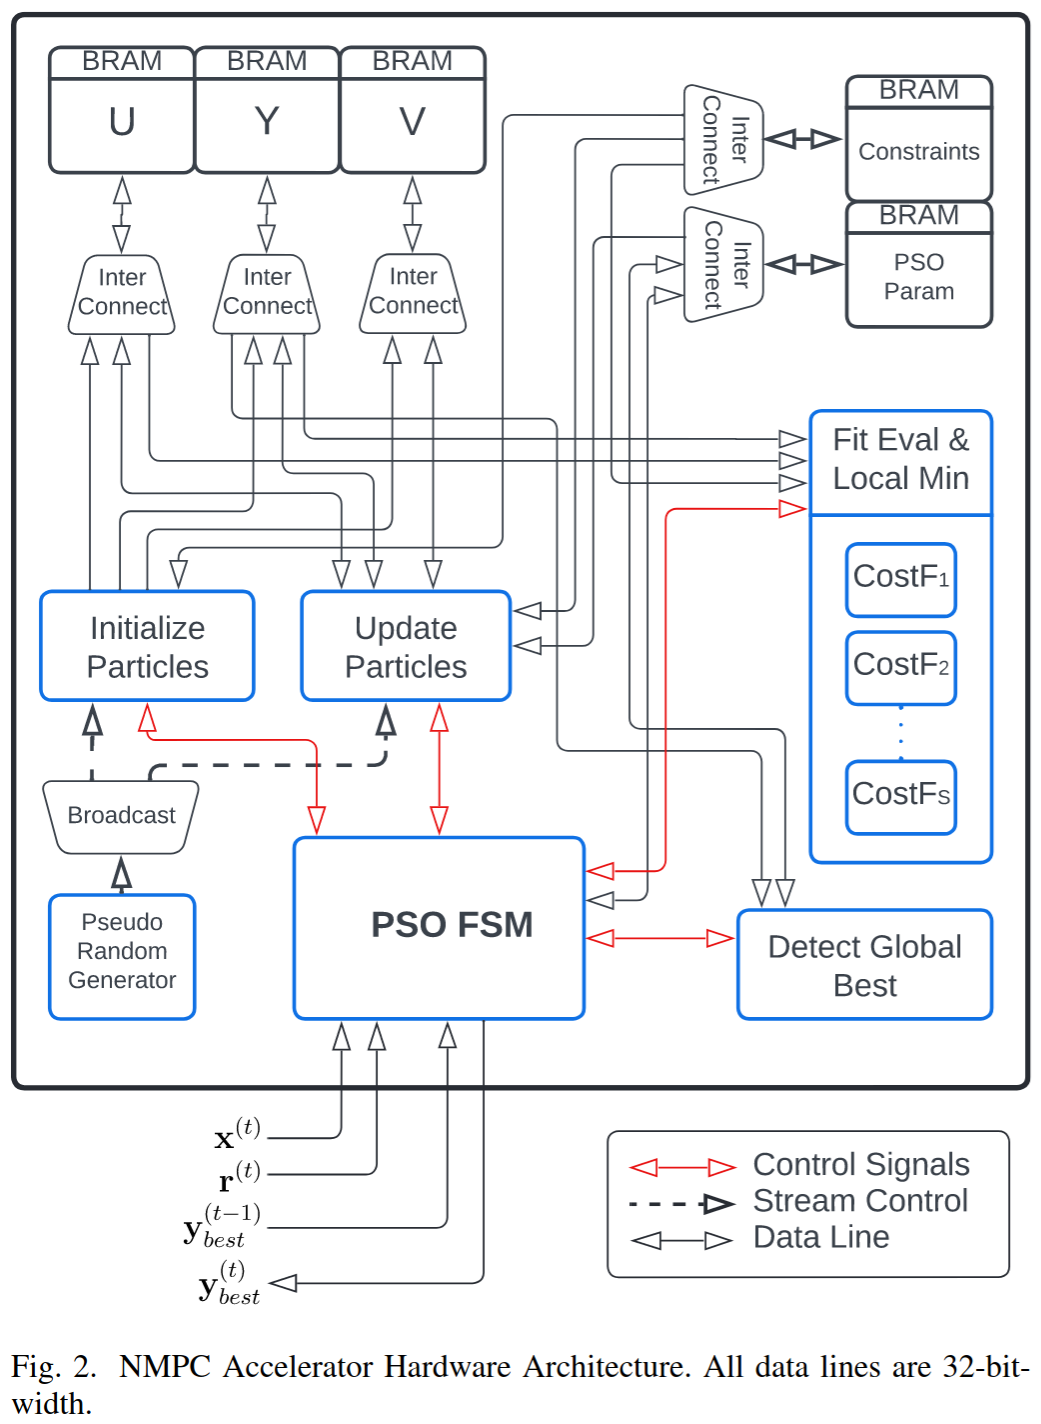

### ROS integration

As mentioned, this work also introduces a ROS node that runs the KPAO-NMPC accelerator and is compatible with two target SoC: (1) **Zynq 7000 SoCTM**, and (2) **Zynq UltraScale+ MPSoCTM** . The computations of the NMPC accelerator are naturally performed on the FPGA of the SoC. For testing purposes, the source code of the NMPC can also be run on the Arm®Cortex®CPU of the possible target SoC.

The NMPC ROS node subscribes to:

i. the current measured state from the sensors $\left(\mathbf{x}\left(t\right)\right)$, 

ii. the current reference trajectory $\left(\mathbf{r}\left(t\right)\right)$ and  

iii. the previous system predicted control horizon ${\mathbf{y}}_{\textrm{best}} \left(t-1\right)$ respectively and as seen in Figs. 2 and 3

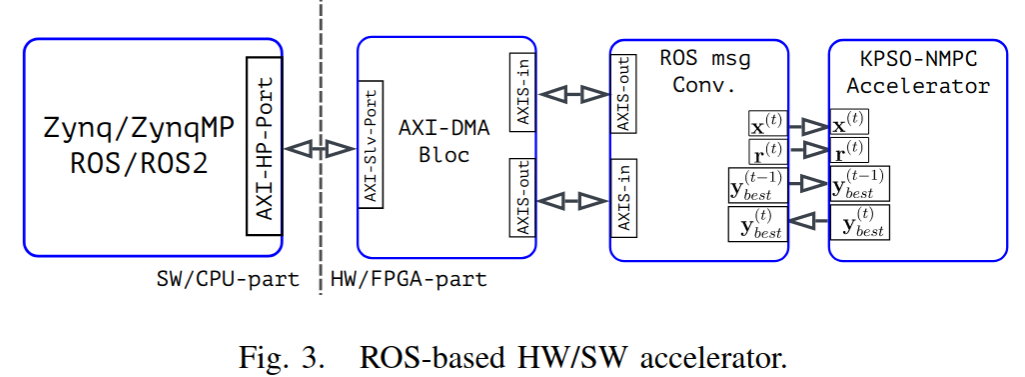

The node then publishes the outcoming estimated control horizon ($y_{\textrm{best}}^{\left(t\right)}$ as seen in Figs. 2 and 3). 

The communciation between SoC CPU and the FPGA leverage the AXI-DMA and a module that serializes/deserializes the transformed messages, as seen in Fig.3

## Evaluation

The case studies for the NMPC are an inverted pendulum system on a cart and a quadrotor drone. The inverted pendulum is described in Fig. 4a. It details the pendulum system whose model is non-linear and are taken from [5]. The states of the inverted pendulum are described by Eqs. (6) and (7):

$x=\left\lbrack x,\theta \;,\dot{x} ,\dot{\theta \;} \right\rbrack$  (6)

$u_{\textrm{ctrl}} =\left\lbrack F\right\rbrack$          (7)

$\left\lbrack x,\theta \;\right\rbrack$ represents the position of the cart and angular position of the pendulum, and $\left\lbrack \dot{x} ,\dot{\theta \;} \right\rbrack$their respective speeds. Finally, $u_{\textrm{ctrl}}$is the force that controls the cart.

The quadrotor drone has four rotors directed upwards from the center of mass of the quadrotor. The mathematical model for the quadrotor dynamics is derived from Euler-Lagrange equations [6]. 

The twelve states for the quadrotor are

$x=\left\lbrack x,y,z,\phi ,\theta ,\psi ,\dot{x} ,\dot{y} ,\dot{z} ,\dot{\phi} ,\dot{\theta} ,\dot{\psi} \right\rbrack$(8)

$u_{\textrm{ctrl}} =\left\lbrack \omega_1^2 ,\omega_2^2 ,\omega_3^2 ,\omega_4^2 \right\rbrack$ (9)

$=\textrm{mma}\left(\left\lbrack \textrm{Throttle},\textrm{Roll},\textrm{Pitch},\textrm{Yaw}\right\rbrack \right)$ (10)

where [x, y, z] denote the spatial position of the quadrotor frame, [φ, θ, ψ] are in the angle positions (roll, pitch, and yaw), and the remaining states are the derivatives of the previously mentioned states. The control inputs for the quadrotor are the squared angular velocities of the four rotors reinterpreted as the command thrust, roll, pitch, and yaw using a motor mixing algorithm (MMA).

### 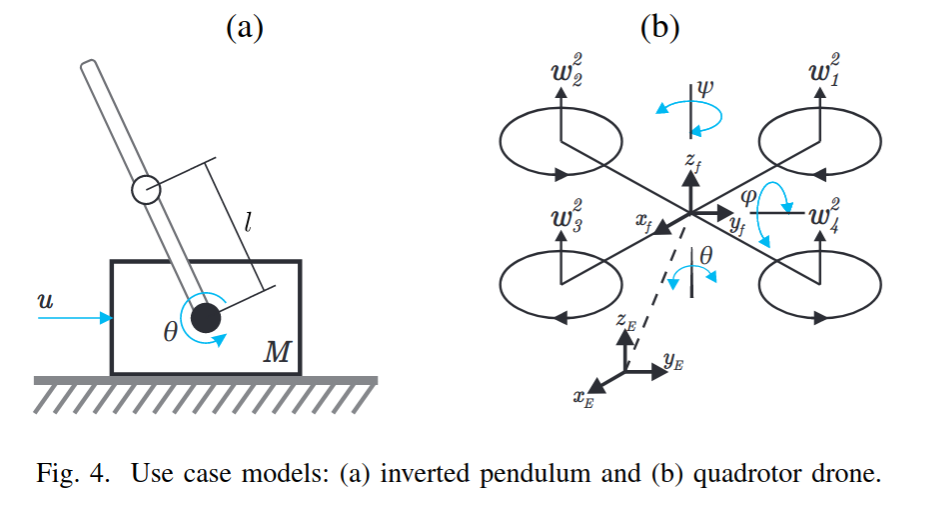

### Algorithm evaluation

A software simulation of the controller is developed to evaluate the NMPC and executed several times to ensure it can solve the NPMC problem correctly. Table I describes the parameters used for these experiments. The number of iterations and particles (kmax, and S respectively) is the smallest value still capable of controlling the system. These values were obtained experimentally and significantly impacted computational performance. The cognitive and social coefficients are set to $c_1 \ge c_2$ because the NMPC problem has multiple local minima with a multi-model search space. For this type of problem, a larger $c_1$is more advantagous given that it causes each particle to be attracted to its individual best position, resulting in a more sparse search [7]

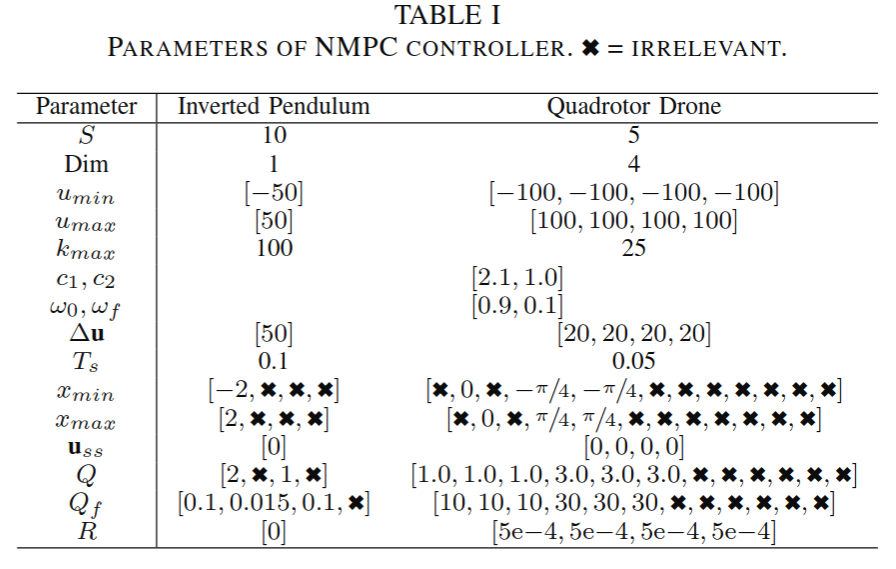

clear all;
close all;
clc

% Define system Parameters for Inverted Pendulum experiment
S = 10 % max particle index 
Dim = 1 % max particle''s dimension
w = 0.9 % inertia factor

% weighting matrices
Q_pendulum = diag([2, 1]) %  intermediate state
Qf_pendulum = diag([0.015, 0.01]) % steady-state
R_pendulum = [0] % control input deviation

k_max = 100 % max iteration
c1 = 2.1 % cognitive coefficient (particle's best)
c2 = 1.0 % social coefficient (global best)

x0_pendulum = diag([0, 0]); % Initial state
u_ss_pendulum = 0; % Steady-state control
x_ss_pendulum = diag([0, 0]); % Steady-state state

u_min_pendulum = -50 
u_max_pendulum = 50
delta_u_min_pendulum = -2
delta_u_max_pendulum = 2

% Real-time requirement
Ts = 0.1

%% Mock defintion of the trajectory reference
% Define time horizon
time_horizon = 0:0.1:10; % Example time vector from 0 to 10 seconds

% Initialize reference trajectory
ref_trajectory_pendulum = zeros(4, length(time_horizon));

% Set desired states over time
x_desired = 4;
theta_desired = 2.5;
xdot_desired = 1;
thetadot_desired = 1;

% Fill the reference trajectory
for t = 1:length(time_horizon)
    ref_trajectory_pendulum(:, t) = [x_desired; theta_desired; xdot_desired; thetadot_desired];
end

y_best_t_minus_1_pendulum = 0 % best next move

J_thresh = 2.0 % cost threshold

Nc = 1 % control horizon
N = 10 % N <= Nc

[y_best_pendulum, J_best_pendulum] = NMPC(x0_pendulum, ref_trajectory_pendulum, y_best_t_minus_1_pendulum, J_thresh, k_max, u_min_pendulum, u_max_pendulum, delta_u_min_pendulum, delta_u_max_pendulum, w, c1, c2, Q_pendulum, Qf_pendulum, R_pendulum, N, Nc, u_ss_pendulum, x_ss_pendulum);



Other parameters in the table are specific to the system and provided by the controller designer, except for Δu. The latter affects the system’s stability during its operation and is limited by its physical constraints. Some values are presented as irrelevant ( ) because they are either not controlled states or measured in degrees (whose values are cyclical). Fig. 5 presents a comparison for the use-cases NMPC control using three solver methods: 1) an Active-Set QuadraticProgramming (QP) as optimal solution [8], 2) a Canonical PSO, and 3) the proposed NMPC. 

Fig. 5 shows struggles of the Canonical PSO to find adequate control solutions in each time iteration and that the system inputs have a considerable variance. On the other hand, the NMPC algorithm can find a stable control for the system reaching the desired reference faster and reducing control action variation after the system reaches the desired position. Finally, it is also possible to determine from Fig. 5 that the proposed NMPC approach can reach a similar solution to QP, considered the optimal solution. 

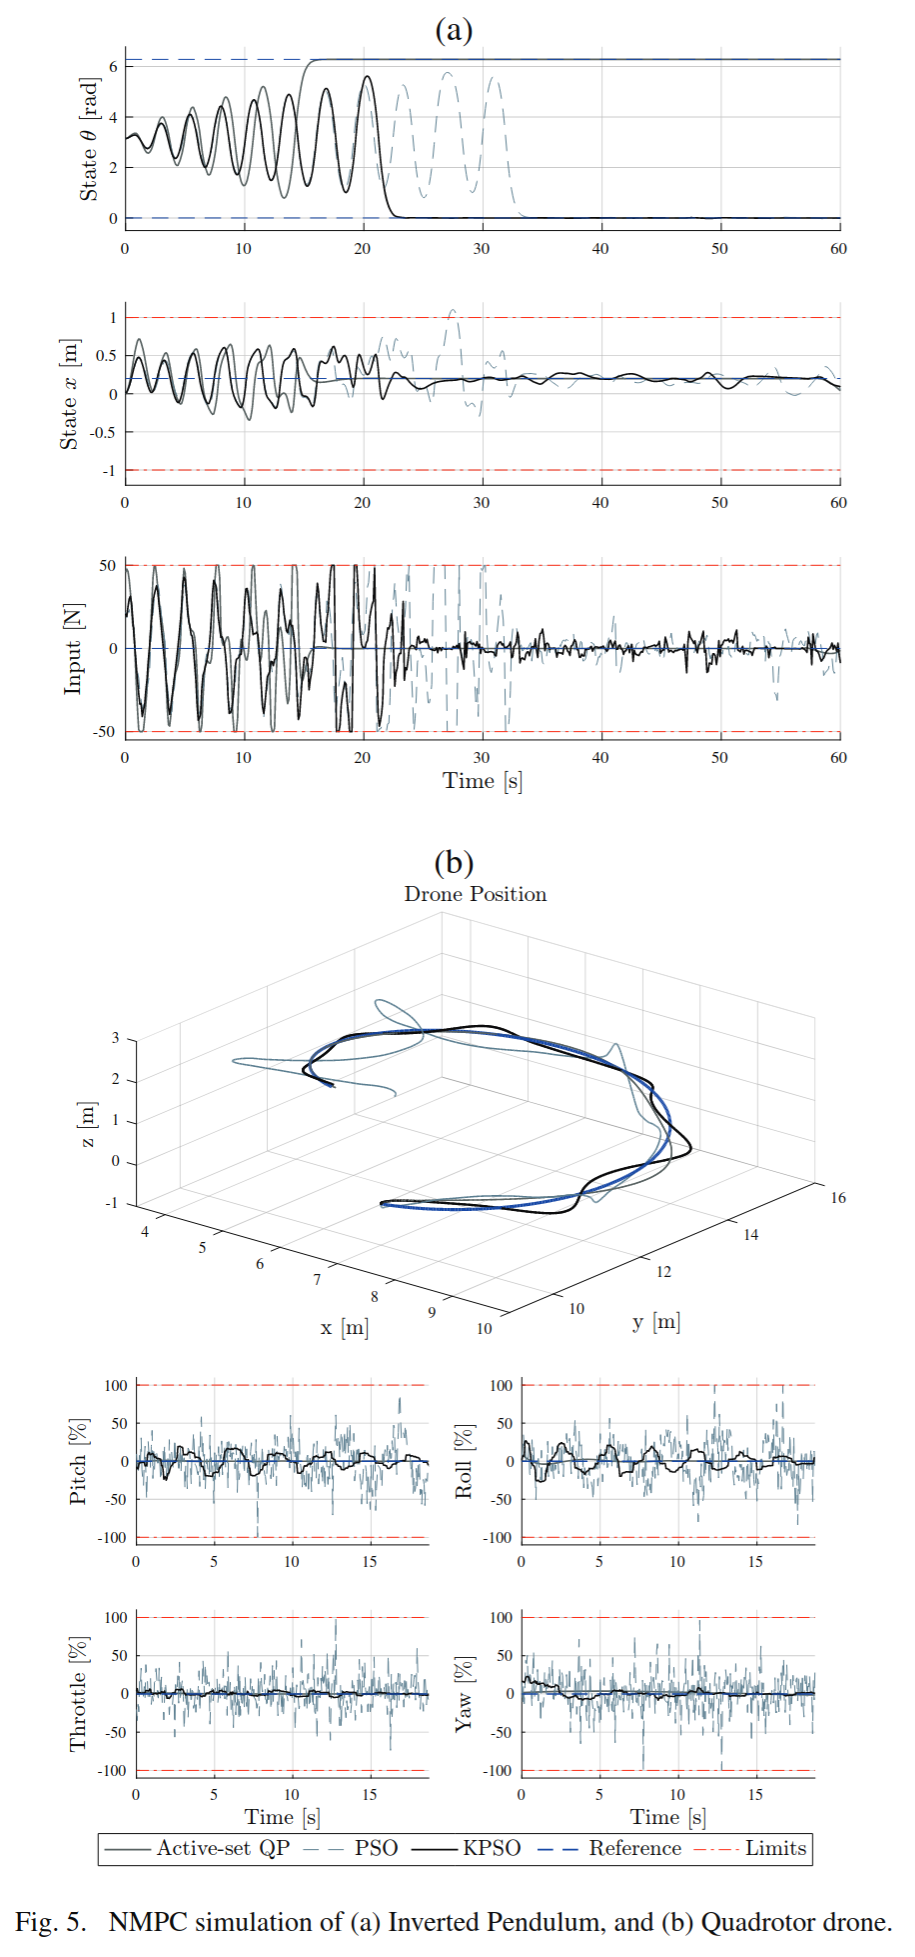

Table II describes the MSE performance of the solvers, and it is split into two parts Error State, and Error Control and are the mean of those values for each time-iteration (see Eq. 3). It further proves the overall improvement of NMPC over canonical PSO and proximity to QP-solution. It is also relevant to mention that, when given a large number of particles and iterations, the Canonical PSO can achieve similar results to the *PSO; however, this results in a more considerable computational effort.

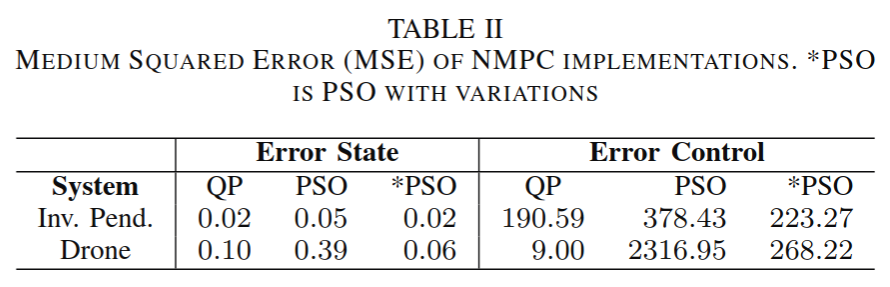

### FPGA implementation results

Two implementations of the NMPC algorithm were compared for the computational performance analysis. The first is a hardware/software co-design solution where the proposed NMPC accelerator runs in hardware. The second is a softwareonly solution in C++ running on the FPGA’s ARM processor on top of the Linux OS. The FPGA evaluation is done on an Ultra96-v2 development board that encloses a Zynq UltraScale+ MPSoCTM . This board is a relatively small device that was selected given that it is an excellent platform that can be used for low-power embedded applications and robotics. Similarly, this onboard evaluation leverages the ROS node described in Section V-D for both the SW and HW accelerated versions, subscribing to simulated sensor data generated by a software model of both the inverted pendulum and drone.

The performance results are summarized in Table III. It can be seen that the accelerator results are comparable to the execution on a Desktop PC and achieve a speed-up of approximately 5x and 8x for the inverted pendulum and quadrotor drone, respectively, with the ARM as a baseline and meets real-time constraints (See Ts in Table I).

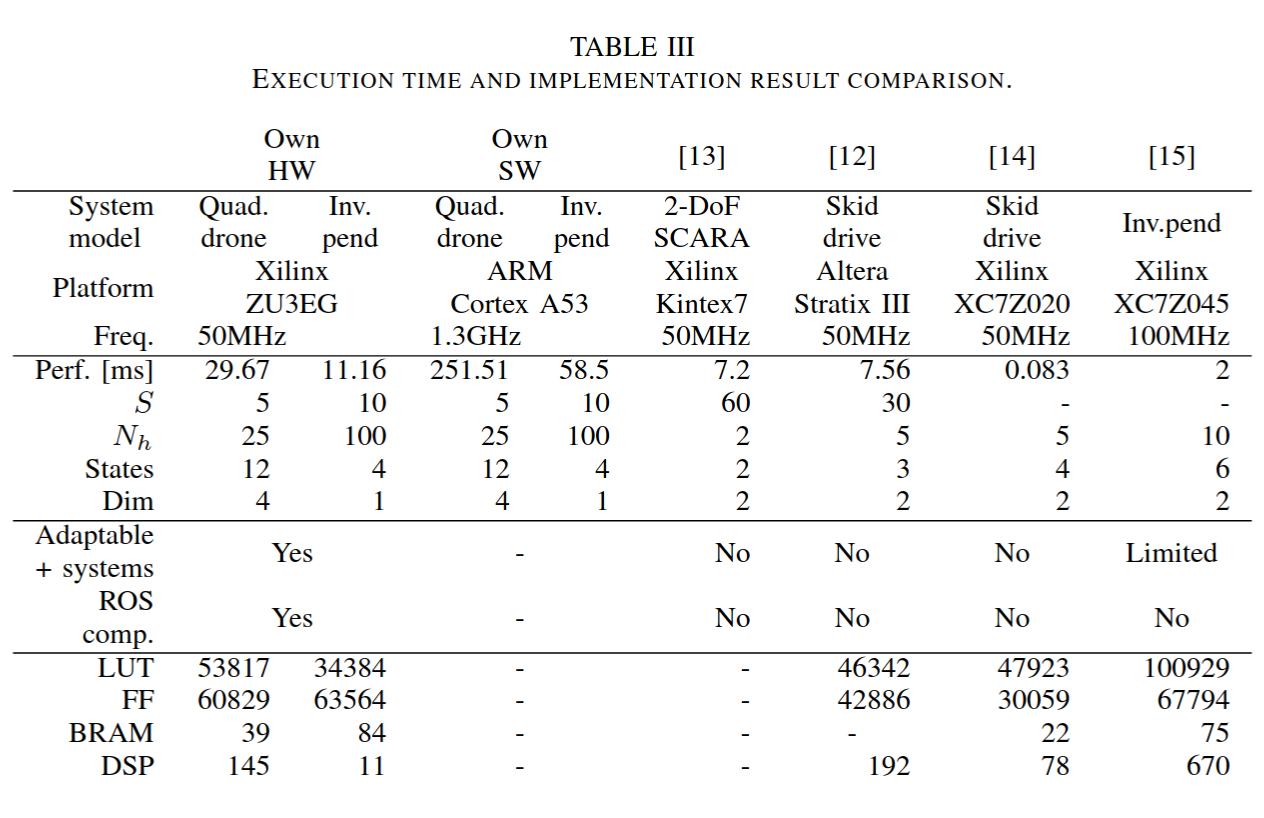

Table III also describe other state-of-the-art implementations. The other deployments use different testbench systems, a 2DoF SCARA, and a skid-drive mobile robot. Given that the systems differ, the number of states and control variables are also mentioned for comparison purposes. The proposed solution shows a similar execution time for a more extensive Nh and S. 

The **Ultra96-v2** board used for this use case has an UltraScale+TM ZU3EG FPGA. The utilization report is summarized at the bottom for the device in Table III. It can be seen that even for a model as complex as the quadrotor drone, the architecture fits (approximately 44% of the target device, while 34% is used for the inverted pendulum). The results also show that the implementation has similar resource utilization to the state-of-the-art deployments, except for DSP, which is lower. On the other hand, the state-of-the-art implementations rely on big FPGAs with higher energy utilization, as demonstrated by benchmarks done on previous works [24]: 0.88mJ, 0.90mJ, and 2.9mJ for the Ultra96, Kintex7 and Stratix III respectively. These results indicate that this work is superior to the others, given that it can achieve a longer prediction horizon  with a smaller device than can potentially drain less energy on runtime. 

Finally, [12], [13] need to make more effort to make their architecture reusable for different applications and focus on the control of specific systems. On the other hand, this implementation brings a framework to add more non-linear systems to the accelerator that is also ROS compatible.

References

  [1] D. Sevis, K. Senel, and Y. Denizhan, “A knowledge‐supported improvement of the PSO method,” *COMPEL - The international journal for computation and mathematics in electrical and electronic engineering*, vol. 32, no. 3, pp. 821–833, Jan. 2013, doi: [10.1108/03321641311305773](https://doi.org/10.1108/03321641311305773).

  [2] B. P. Zeigler, A. Muzy, and E. Kofman, “Chapter 3 - Modeling Formalisms and Their Simulators,” in *Theory of Modeling and Simulation (Third Edition)*, B. P. Zeigler, A. Muzy, and E. Kofman, Eds., Academic Press, 2019, pp. 43–91. doi: [10.1016/B978-0-12-813370-5.00011-0](https://doi.org/10.1016/B978-0-12-813370-5.00011-0).

  [3] "Park-Miller-Carta Pseudo-Random Number Generators.” [Online]. Available: [https://www.firstpr.com.au/dsp/rand31/](https://www.firstpr.com.au/dsp/rand31/)

  [4] A. Podlubne, J. Mey, R. Schöne, U. Aßmann, and D. Göhringer, “Model-Based Approach for Automatic Generation of Hardware Architectures for Robotics,” *IEEE Access*, vol. 9, pp. 140921–140937, 2021, doi: [10.1109/ACCESS.2021.3119061](https://doi.org/10.1109/ACCESS.2021.3119061).  